多个 net

function visualize_all_nets_routing_results(enable_all, single_net_name)
    % 主函数：可视化所有net的布线结果
    log_file = 'all_nets.log';

    % 解析所有net的日志文件
    all_nets_data = parse_all_nets_log_file(log_file);
    
    fprintf('成功解析了 %d 个net的数据\n', length(all_nets_data));
    
    % 为每个值创建可视化
    values_to_visualize = {'value1', 'value2', 'value3', 'value4', 'value5'};
    value_names = {'Current type', 'History reusable times', 'History non-reusable times', 'Cost reuse', 'Cost non-reuse'};
    
    for i = 1:length(values_to_visualize)
        if (enable_all)
            create_all_nets_value_visualization(all_nets_data, values_to_visualize{i}, value_names{i}, i);
        else
            create_single_net_value_visualization(all_nets_data, single_net_name, values_to_visualize{i}, value_names{i}, i);
        end
    end
end

function all_nets_data = parse_all_nets_log_file(filename)
    % 解析整个日志文件，提取所有net的信息
    all_nets_data = [];
    
    fid = fopen(filename, 'r');
    if fid == -1
        error('无法打开文件: %s', filename);
    end
    
    current_net = struct('name', '', 'tracks', [], 'cobs', []);
    net_content = {};
    is_net_section = false;
    
    while ~feof(fid)
        line = fgetl(fid);
        
        if isempty(line)
            continue;
        end
        
        % 检测net信息开始
        if contains(line, 'HardwareRecorder Status')
            is_net_section = true;
            continue;
        % 检测net信息结束
        elseif contains(line, 'END HardwareRecorder Status')
            is_net_section = false;
            if ~isempty(current_net.name)
                [tracks, cobs] = parse_net_content(net_content);
                current_net.tracks = tracks;
                current_net.cobs = cobs;
                all_nets_data = [all_nets_data; current_net];
            end
            break;
        % 检测net名称
        elseif contains(line, 'Net Name:') && is_net_section
            % 存上一个
            if ~isempty(current_net.name)
                [tracks, cobs] = parse_net_content(net_content);
                current_net.tracks = tracks;
                current_net.cobs = cobs;
                all_nets_data = [all_nets_data; current_net];
            end
            current_net = struct('name', '', 'tracks', [], 'cobs', []);
            net_content = {};
            
            % 处理当前 net
            tokens = regexp(line, 'Net Name:\s*(.+)', 'tokens');
            if ~isempty(tokens)
                current_net.name = strtrim(tokens{1}{1});
            end
        elseif is_net_section
            net_content{end+1} = line;
        else
            continue;
        end
    end
end

function [tracks, cobs] = parse_net_content(net_content)
    % 解析单个net的内容
    tracks = [];
    cobs = [];
    
    current_section = '';
    current_data = [];
    
    for i = 1:length(net_content)
        line = net_content{i};
        
        % 检测新的section开始
        if contains(line, 'Track_reg at')
            if ~isempty(current_section) && ~isempty(current_data)
                if strcmp(current_section, 'track')
                    tracks = [tracks; current_data];
                elseif strcmp(current_section, 'cob')
                    cobs = [cobs; current_data];
                end
            end
            
            current_section = 'track';
            current_data = parse_track_header(line);
            
        elseif contains(line, 'COB_reg at')
            if ~isempty(current_section) && ~isempty(current_data)
                if strcmp(current_section, 'track')
                    tracks = [tracks; current_data];
                elseif strcmp(current_section, 'cob')
                    cobs = [cobs; current_data];
                end
            end
            
            current_section = 'cob';
            current_data = parse_cob_header(line);
            
        elseif contains(line, '----') && ~isempty(current_section)
            % section结束
            if ~isempty(current_section) && ~isempty(current_data)
                if strcmp(current_section, 'track')
                    tracks = [tracks; current_data];
                elseif strcmp(current_section, 'cob')
                    cobs = [cobs; current_data];
                end
            end
            
            current_section = '';
            current_data = [];
            
        elseif ~isempty(current_section) && contains(line, ':')
            % 解析数据行
            if strcmp(current_section, 'track') || strcmp(current_section, 'cob')
                current_data = parse_data_line(current_data, line);
            end
        end
    end
    
    % 处理最后一个section
    if ~isempty(current_section) && ~isempty(current_data)
        if strcmp(current_section, 'track')
            tracks = [tracks; current_data];
        elseif strcmp(current_section, 'cob')
            cobs = [cobs; current_data];
        end
    end
end

function create_single_net_value_visualization(cycle, all_nets_data, net_name, value_field, value_name, fig_num)
    % 创建单个net的单个值的可视化
    
    % 从所有net数据中查找指定名称的net
    target_net = [];
    for i = 1:length(all_nets_data)
        if strcmp(all_nets_data(i).name, net_name)
            target_net = all_nets_data(i);
            break;
        end
    end
    
    if isempty(target_net)
        warning('未找到名为 "%s" 的net', net_name);
        return;
    end
    
    fprintf('正在可视化net: %s - %s\n', net_name, value_name);
    
    figure('Position', [100+200*(fig_num-1), 100, 1200, 900], ...
           'Name', sprintf('单个Net布线结果可视化 - %s - %s', net_name, value_name));
    
    % 绘制基础硬件结构
    draw_base_hardware();
    
    % 收集该net的所有值用于颜色映射
    all_values = [];
    
    % 处理Track数据
    for i = 1:length(target_net.tracks)
        if ~isempty(target_net.tracks(i).entries)
            values = [target_net.tracks(i).entries.(value_field)];
            all_values = [all_values; values(~isnan(values))];
        end
    end
    
    % 处理COB数据
    for i = 1:length(target_net.cobs)
        if ~isempty(target_net.cobs(i).entries)
            values = [target_net.cobs(i).entries.(value_field)];
            all_values = [all_values; values(~isnan(values))];
        end
    end
    
    if isempty(all_values)
        warning('在net "%s" 中没有找到有效的%s数据', net_name, value_name);
        return;
    end
    
    % 创建颜色映射
    min_val = min(min(all_values));
    max_val = max(max(all_values));
    
    % 绘制Track数据
    for i = 1:length(target_net.tracks)
        track = target_net.tracks(i);
        if isempty(track.entries)
            continue;
        end
        draw_track_values_single_net(track, value_field, min_val, max_val);
    end
    
    % 绘制COB数据
    for i = 1:length(target_net.cobs)
        cob = target_net.cobs(i);
        if isempty(cob.entries)
            continue;
        end
        draw_cob_values_single_net(cob, value_field, min_val, max_val);
    end
    
    % 添加颜色条和标题
    colormap(jet);
    c = colorbar;
    c.Label.String = value_name;
    if min_val == max_val
        caxis([min_val-1, max_val+1]);
    else
        caxis([min_val, max_val]);
    end
    
    title(sprintf('cycle %d, 单个Net布线算法中间结果 - %s\n%s', cycle, value_name, net_name), ...
          'FontSize', 14, 'FontWeight', 'bold');
    
    % 添加图例显示net名称
    add_single_net_legend(net_name);
end

function draw_track_values_single_net(track, value_field, min_val, max_val)
    % 绘制Track的值（单个net版本）
    x = track.x;
    y = track.y;
    
    if strcmp(track.direction, 'Vertical')
        % 垂直路由通道 - 在COB下方
        track_x_start = x - 0.25;
        track_y_start = y - 0.75;
        track_y_length = 0.5;
        track_x_width = 0.4/128;
        track_x_interval = 0.5/128;
        
        for i = 1:length(track.entries)
            entry = track.entries(i);
            if isnan(entry.(value_field))
                continue;
            end
            
            % 计算位置（128条轨道均匀分布）
            pos_index = entry.number;
            segment_x = track_x_start + track_x_interval * pos_index;
            
            % 计算颜色
            color_val = (entry.(value_field) - min_val) / (max_val - min_val);
            color = get_color_from_value(color_val);
            
            % 绘制轨道段
            rectangle('Position', [segment_x, track_y_start, track_x_width, track_y_length], ...
                      'FaceColor', color, 'EdgeColor', 'none');
        end
        
    else % Horizontal
        % 水平路由通道 - 在COB左侧
        track_x_start = x - 0.75;
        track_y_start = y - 0.25;
        track_x_length = 0.5;
        track_y_width = 0.4/128;
        track_y_interval = 0.5/128;
        
        for i = 1:length(track.entries)
            entry = track.entries(i);
            if isnan(entry.(value_field))
                continue;
            end
            
            % 计算位置（128条轨道均匀分布）
            pos_index = entry.number;
            segment_y = track_y_start + track_y_interval * pos_index;
            
            % 计算颜色
            color_val = (entry.(value_field) - min_val) / (max_val - min_val);
            color = get_color_from_value(color_val);
            
            % 绘制轨道段
            rectangle('Position', [track_x_start, segment_y, track_x_length, track_y_width], ...
                      'FaceColor', color, 'EdgeColor', 'none');
        end
    end
end

function draw_cob_values_single_net(cob, value_field, min_val, max_val)
    % 绘制COB的值（单个net版本）
    x = cob.x;
    y = cob.y;
    direction = cob.direction;
   
    
    for i = 1:length(cob.entries)
        entry = cob.entries(i);
        if isnan(entry.(value_field))
            continue;
        end
        
        % 计算颜色
        color_val = (entry.(value_field) - min_val) / (max_val - min_val);
        color = get_color_from_value(color_val);
        
        % 根据方向计算端口位置
        pos_ratio = entry.number / 127;
        port_width = 0.45 / 128;
        port_height = 0.45 / 128;
        
        switch direction
            case 'R' % 右边
                port_x = x + 0.25;
                port_y = y - 0.25 + 0.5 * pos_ratio;
                rectangle('Position', [port_x-0.05, port_y, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'L' % 左边
                port_x = x - 0.25;
                port_y = y - 0.25 + 0.5 * pos_ratio;
                rectangle('Position', [port_x+0.05, port_y, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'U' % 上边
                port_x = x - 0.25 + 0.5 * pos_ratio;
                port_y = y + 0.25;
                rectangle('Position', [port_x, port_y-0.05, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'D' % 下边
                port_x = x - 0.25 + 0.5 * pos_ratio;
                port_y = y - 0.25;
                rectangle('Position', [port_x, port_y+0.05, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
        end
    end
end

function color = get_color_from_value(value)
    % 根据归一化值获取颜色
    % 使用jet颜色映射
    cmap = jet(256);
    idx = max(1, min(256, round(value * 255) + 1));
    color = cmap(idx, :);
end

function add_single_net_legend(net_name)
    % 添加单个net的图例
    legend_elements = [];
    legend_labels = {};
    
    % 简化net名称用于图例
    if length(net_name) > 30
        legend_label = [net_name(1:27) '...'];
    else
        legend_label = net_name;
    end
    
    h_net = plot(NaN, NaN, 's', 'MarkerSize', 12, 'MarkerFaceColor', [0.2, 0.6, 1.0], ...
                 'MarkerEdgeColor', 'k', 'LineWidth', 2);
    legend_elements = [legend_elements, h_net];
    legend_labels = [legend_labels, legend_label];
    
    legend(legend_elements, legend_labels, 'Location', 'northeastoutside', ...
           'FontSize', 10, 'FontWeight', 'bold');
end


function create_all_nets_value_visualization(cycle, all_nets_data, value_field, value_name, fig_num)
    % 创建所有net的单个值的可视化
    
    figure('Position', [100+200*(fig_num-1), 100, 1200, 900], ...
           'Name', sprintf('所有Net布线结果可视化 - %s', value_name));
    
    % 绘制基础硬件结构
    draw_base_hardware();
    
    % 收集所有net的所有值用于颜色映射
    all_values = [];
    for net_idx = 1:length(all_nets_data)
        net = all_nets_data(net_idx);
        
        % 处理Track数据
        for i = 1:length(net.tracks)
            if ~isempty(net.tracks(i).entries)
                values = [net.tracks(i).entries.(value_field)];
                all_values = [all_values; values(~isnan(values))];
            end
        end
        
        % 处理COB数据
        for i = 1:length(net.cobs)
            if ~isempty(net.cobs(i).entries)
                values = [net.cobs(i).entries.(value_field)];
                all_values = [all_values; values(~isnan(values))];
            end
        end
    end
    
    if isempty(all_values)
        warning('没有找到有效的%s数据', value_name);
        return;
    end
    
    % 创建颜色映射
    min_val = min(min(all_values));
    max_val = max(max(all_values));
    
    % 为每个net分配不同的透明度，以便区分
    num_nets = length(all_nets_data);
    alphas = linspace(0.3, 0.8, num_nets); % 不同透明度
    
    % 绘制所有net的数据
    for net_idx = 1:num_nets
        net = all_nets_data(net_idx);
        net_name = net.name;
        alpha = alphas(net_idx);
        
        % 绘制Track数据
        for i = 1:length(net.tracks)
            track = net.tracks(i);
            if isempty(track.entries)
                continue;
            end
            draw_track_values_all_nets(track, value_field, min_val, max_val, alpha, net_idx);
        end
        
        % 绘制COB数据
        for i = 1:length(net.cobs)
            cob = net.cobs(i);
            if isempty(cob.entries)
                continue;
            end
            draw_cob_values_all_nets(cob, value_field, min_val, max_val, alpha, net_idx);
        end
    end
    
    % 添加颜色条和标题
    colormap(jet);
    c = colorbar;
    c.Label.String = value_name;
    if min_val == max_val
        caxis([min_val-1, max_val+1]);
    else
        caxis([min_val, max_val]);
    end
    
    title(sprintf('cycle %d, 所有Net布线算法中间结果 - %s\n(共%d个net)', cycle, value_name, num_nets), ...
          'FontSize', 14, 'FontWeight', 'bold');
    
    % 添加图例
    % add_all_nets_legend(all_nets_data, alphas);
end

function draw_track_values_all_nets(track, value_field, min_val, max_val, alpha, net_idx)
    % 绘制Track的值（所有net版本）
    x = track.x;
    y = track.y;
    
    if strcmp(track.direction, 'Vertical')
        % 垂直路由通道 - 在COB下方
        track_x_start = x - 0.25;
        track_y_start = y - 0.75;
        track_y_length = 0.5;
        track_x_width = 0.4/128;
        track_x_interval = 0.5/128;
        
        for i = 1:length(track.entries)
            entry = track.entries(i);
            if isnan(entry.(value_field))
                continue;
            end
            
            % 计算位置（128条轨道均匀分布）
            pos_index = entry.number;
            segment_x = track_x_start + track_x_interval * pos_index;
            
            % 计算颜色
            color_val = (entry.(value_field) - min_val) / (max_val - min_val);
            color = get_color_from_value(color_val);
            
            % 绘制轨道段
            rectangle('Position', [segment_x, track_y_start, track_x_width, track_y_length], ...
                      'FaceColor', color, 'EdgeColor', 'none');
        end
        
    else % Horizontal
        % 水平路由通道 - 在COB左侧
        track_x_start = x - 0.75;
        track_y_start = y - 0.25;
        track_x_length = 0.5;
        track_y_width = 0.4/128;
        track_y_interval = 0.5/128;
        
        for i = 1:length(track.entries)
            entry = track.entries(i);
            if isnan(entry.(value_field))
                continue;
            end
            
            % 计算位置（128条轨道均匀分布）
            pos_index = entry.number;
            segment_y = track_y_start + track_y_interval * pos_index;
            
            % 计算颜色
            color_val = (entry.(value_field) - min_val) / (max_val - min_val);
            color = get_color_from_value(color_val);
            
            % 绘制轨道段
            rectangle('Position', [track_x_start, segment_y, track_x_length, track_y_width], ...
                      'FaceColor', color, 'EdgeColor', 'none');
        end
    end
end

function draw_cob_values_all_nets(cob, value_field, min_val, max_val, alpha, net_idx)
    % 绘制COB的值（所有net版本）
    x = cob.x;
    y = cob.y;
    direction = cob.direction;
   
    
    for i = 1:length(cob.entries)
        entry = cob.entries(i);
        if isnan(entry.(value_field))
            continue;
        end
        
        % 计算颜色
        color_val = (entry.(value_field) - min_val) / (max_val - min_val);
        color = get_color_from_value(color_val);
        
        % 根据方向计算端口位置
        pos_ratio = entry.number / 127;
        port_width = 0.45 / 128;
        port_height = 0.45 / 128;
        
        switch direction
            case 'R' % 右边
                port_x = x + 0.25;
                port_y = y - 0.25 + 0.5 * pos_ratio;
                rectangle('Position', [port_x-0.05, port_y, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'L' % 左边
                port_x = x - 0.25;
                port_y = y - 0.25 + 0.5 * pos_ratio;
                rectangle('Position', [port_x+0.05, port_y, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'U' % 上边
                port_x = x - 0.25 + 0.5 * pos_ratio;
                port_y = y + 0.25;
                rectangle('Position', [port_x, port_y-0.05, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
                
            case 'D' % 下边
                port_x = x - 0.25 + 0.5 * pos_ratio;
                port_y = y - 0.25;
                rectangle('Position', [port_x, port_y+0.05, port_width, port_height], ...
                          'FaceColor', color, 'EdgeColor', 'k', 'LineWidth', 0.5);
        end
    end
end

function color = get_color_from_value_all_nets(value, base_color, alpha)
    % 根据归一化值获取颜色（所有net版本）
    % 使用基础颜色和值来混合
    intensity = value; % 使用值作为强度
    color = base_color * intensity + [1, 1, 1] * (1 - intensity);
    color = [color, alpha]; % 添加透明度
end

function add_all_nets_legend(all_nets_data, alphas)
    % 添加所有net的图例
    legend_elements = [];
    legend_labels = {};
    
    % 为前几个net添加图例（避免图例过多）
    max_legend_nets = min(8, length(all_nets_data));
    
    for i = 1:max_legend_nets
        net = all_nets_data(i);
        % 简化net名称用于图例
        if length(net.name) > 20
            legend_label = [net.name(1:17) '...'];
        else
            legend_label = net.name;
        end
        
        h_net = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', [0.7, 0.7, 0.7], ...
                     'MarkerEdgeColor', 'k');
        legend_elements = [legend_elements, h_net];
        legend_labels = [legend_labels, legend_label];
    end
    
    % 如果net数量超过图例显示限制，添加提示
    if length(all_nets_data) > max_legend_nets
        h_more = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', [0.5, 0.5, 0.5], ...
                      'MarkerEdgeColor', 'k');
        legend_elements = [legend_elements, h_more];
        legend_labels = [legend_labels, sprintf('和其他%d个net', length(all_nets_data)-max_legend_nets)];
    end
    
    legend(legend_elements, legend_labels, 'Location', 'northeastoutside', ...
           'FontSize', 8, 'NumColumns', 1);
end

function track_data = parse_track_header(line)
    % 解析Track header行
    track_data = struct();
    
    % 提取坐标和方向
    tokens = regexp(line, 'Track_reg at (\d+), (\d+), kiwi::hardware::TrackDirection::(\w+)', 'tokens');
    if ~isempty(tokens)
        track_data.y = str2double(tokens{1}{1});
        track_data.x = str2double(tokens{1}{2});
        track_data.direction = tokens{1}{3};
        track_data.type = 'track';
        track_data.entries = [];
    end
end

function cob_data = parse_cob_header(line)
    % 解析COB header行
    cob_data = struct();
    
    % 提取坐标和方向
    tokens = regexp(line, 'COB_reg at (\d+), (\d+), ([RLUD])', 'tokens');
    if ~isempty(tokens)
        cob_data.y = str2double(tokens{1}{1});
        cob_data.x = str2double(tokens{1}{2});
        cob_data.direction = tokens{1}{3};
        cob_data.type = 'cob';
        cob_data.entries = [];
    end
end

function data = parse_data_line(data, line)
    % 解析数据行
    if isempty(data)
        return;
    end
    
    % 使用正则表达式提取所有数值信息
    pattern = '(\d+): Current type: (\S+), History reusable times: ([\d.]+), History non-reusable times: ([\d.]+), Cost reuse: ([\d.]+), Cost non-reuse: ([\d.]+)';
    tokens = regexp(line, pattern, 'tokens');
    
    if ~isempty(tokens)
        entry = struct();
        entry.number = str2double(tokens{1}{1});
        
        % 处理Current type（可能是None或数字）
        if strcmp(tokens{1}{2}, 'None')
            entry.value1 = -1;
        else
            entry.value1 = str2double(tokens{1}{2});
        end
        
        entry.value2 = str2double(tokens{1}{3});
        entry.value3 = str2double(tokens{1}{4});
        entry.value4 = str2double(tokens{1}{5});
        entry.value5 = str2double(tokens{1}{6});
        
        data.entries = [data.entries; entry];
    end
end

function draw_base_hardware()
    % 绘制基础硬件结构
    hold on;
    axis equal;
    grid on;
    xlim([-0.5, 11.5]);
    ylim([-0.5, 8.5]);
    xlabel('X 坐标');
    ylabel('Y 坐标');
    
    % 绘制路由通道网格
    draw_routing_grid();
    
    % 绘制COB
    draw_all_cobs();
    
    % 绘制TOB
    draw_all_tobs();
end

function draw_routing_grid()
    % 绘制路由通道网格
    grid_x = 12;
    grid_y = 9;
    
    % 水平路由通道
    for i = 0:grid_y-1
        plot([0, grid_x-1], [i, i], 'b-', 'LineWidth', 3, 'Color', [0.2, 0.2, 0.8, 0.3]);
    end
    
    % 垂直路由通道
    for i = 0:grid_x-1
        plot([i, i], [0, grid_y-1], 'b-', 'LineWidth', 3, 'Color', [0.2, 0.2, 0.8, 0.3]);
    end
end

function draw_all_cobs()
    % 绘制所有COB
    cob_color = [0.1, 0.6, 0.3, 0.3]; % 半透明绿色
    
    for i = 0:11
        for j = 0:8
            % 跳过TOB位置
            if (i == 0 && j == 0.5) || (i == 3 && j == 0.5) || (i == 6 && j == 0.5) || (i == 9 && j == 0.5) || ...
               (i == 0 && j == 2.5) || (i == 3 && j == 2.5) || (i == 6 && j == 2.5) || (i == 9 && j == 2.5) || ...
               (i == 0 && j == 4.5) || (i == 3 && j == 4.5) || (i == 6 && j == 4.5) || (i == 9 && j == 4.5) || ...
               (i == 0 && j == 6.5) || (i == 3 && j == 6.5) || (i == 6 && j == 6.5) || (i == 9 && j == 6.5)
                continue;
            end
            
            rectangle('Position', [i-0.25, j-0.25, 0.5, 0.5], ...
                      'FaceColor', cob_color, 'EdgeColor', 'k', 'LineWidth', 1);
            
            text(i, j, 'COB', 'HorizontalAlignment', 'center', ...
                 'VerticalAlignment', 'middle', 'FontWeight', 'bold', 'FontSize', 7, 'Color', 'white');
        end
    end
end

function draw_all_tobs()
    % 绘制所有TOB
    tob_positions = [
        0, 0.5; 3, 0.5; 6, 0.5; 9, 0.5;
        0, 2.5; 3, 2.5; 6, 2.5; 9, 2.5;
        0, 4.5; 3, 4.5; 6, 4.5; 9, 4.5;
        0, 6.5; 3, 6.5; 6, 6.5; 9, 6.5
    ];
    
    tob_color = [0.9, 0.5, 0.1, 0.3]; % 半透明橙色
    
    for i = 1:size(tob_positions, 1)
        pos = tob_positions(i, :);
        rectangle('Position', [pos(1)-0.4, pos(2)-0.15, 0.8, 0.3], ...
                  'FaceColor', tob_color, 'EdgeColor', 'k', 'LineWidth', 1);
        
        text(pos(1), pos(2), 'TOB', 'HorizontalAlignment', 'center', ...
             'VerticalAlignment', 'middle', 'FontWeight', 'bold', 'FontSize', 8, 'Color', 'white');
    end
end



% 运行可视化
% visualize_all_nets_routing_results(false, "SyncNet in group 1");


多轮

成功解析了 5 个cycle的数据
正在可视化第1个cycle的数据


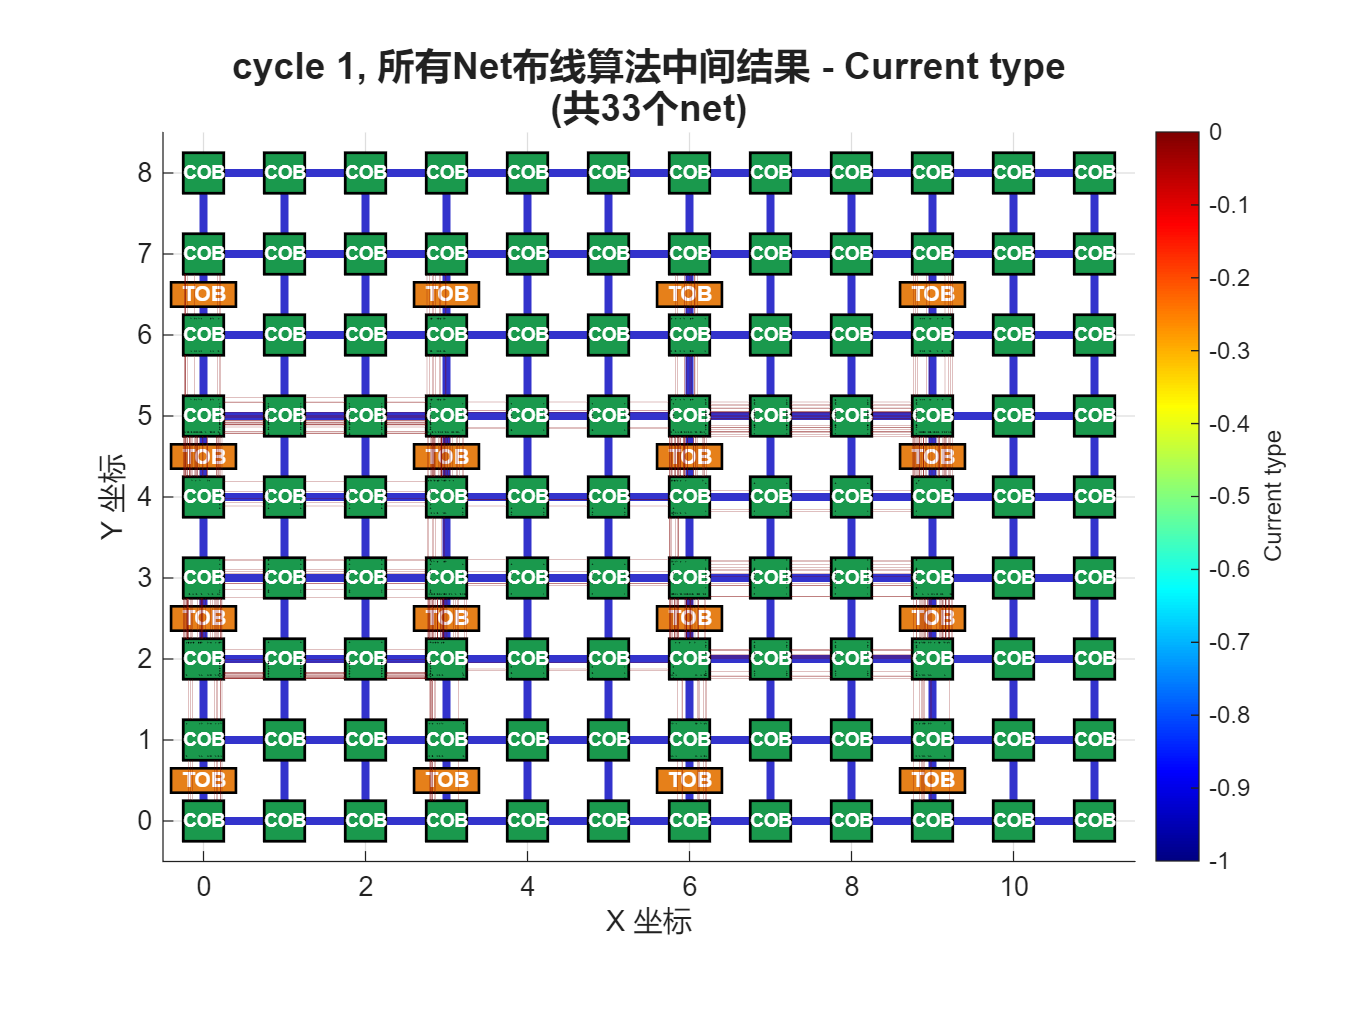

正在可视化第2个cycle的数据


正在可视化第3个cycle的数据


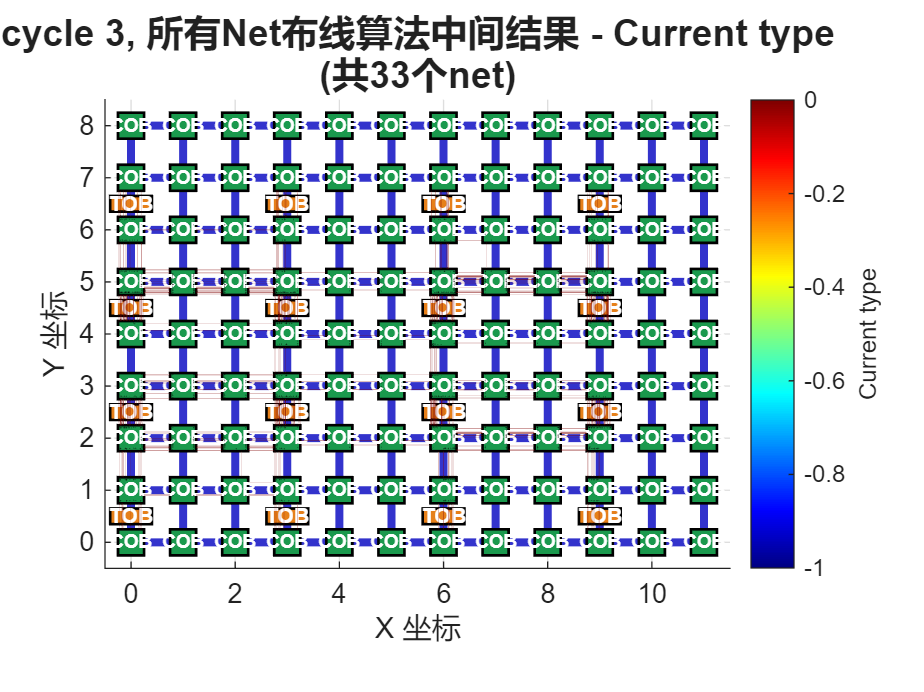

正在可视化第4个cycle的数据


正在可视化第5个cycle的数据


function visualize_all_cycles_routing_results(enable_all, net_name, begin_cycle, end_cycle, values_to_visualize, value_names)
    % 主函数：可视化所有net的布线结果
    log_file = 'debug.log';

    % 解析所有net的日志文件
    all_cycles_data = parse_all_cycles_log_file(log_file, begin_cycle, end_cycle);
    
    fprintf('成功解析了 %d 个cycle的数据\n', length(all_cycles_data));
        
    for cycle = begin_cycle:1:end_cycle
        fprintf('正在可视化第%d个cycle的数据\n', cycle);
        current_cycle = all_cycles_data(cycle-begin_cycle+1);
        for i = 1:length(values_to_visualize)
            if (enable_all)
                create_all_nets_value_visualization(current_cycle.cycle, current_cycle.all_nets_data, values_to_visualize{i}, value_names{i}, i);
            else
                create_single_net_value_visualization(current_cycle.cycle, current_cycle.all_nets_data, net_name, values_to_visualize{i}, value_names{i}, i);
            end
        end
    end
end


function all_cycles_data = parse_all_cycles_log_file(filename, begin_cycle, end_cycle)
    all_cycles_data = [];
    current_cycle = struct('cycle', '', 'all_nets_data', []);
    
    fid = fopen(filename, 'r');
    if fid == -1
        error('无法打开文件: %s', filename);
    end
    
    all_nets_data = [];
    current_net = struct('name', '', 'tracks', [], 'cobs', []);
    net_content = {};
    is_net_section = false;
    is_cycle_section = false;
    
    while ~feof(fid)
        line = fgetl(fid);
        
        if isempty(line)
            continue;
        end
        
        if ~isempty(regexp(line, 'cycle \d+ start', 'once'))
            tokens = regexp(line, 'cycle (\d+) start', 'tokens');
            cycle_number = str2double(tokens{1}{1});
            
            if (cycle_number >= begin_cycle && cycle_number <= end_cycle)
                is_cycle_section = true;
            elseif (cycle_number > end_cycle)
                break;
            end
            current_net = struct('name', '', 'tracks', [], 'cobs', []);
            net_content = {};
            is_net_section = false;
            current_cycle = struct('cycle', '', 'all_nets_data', []);
            all_nets_data = [];
        elseif ~isempty(regexp(line, '--------Cycle \d+--------', 'once')) && is_cycle_section
            is_cycle_section = false;
            current_cycle.cycle = cycle_number;
            current_cycle.all_nets_data = all_nets_data;
            all_cycles_data = [all_cycles_data; current_cycle];
        end
        
        if is_cycle_section
            % 检测net信息开始
            if contains(line, 'HardwareRecorder Status')
                is_net_section = true;
                continue;
            % 检测net信息结束
            elseif contains(line, 'END HardwareRecorder Status')
                is_net_section = false;
                if ~isempty(current_net.name)
                    [tracks, cobs] = parse_net_content(net_content);
                    current_net.tracks = tracks;
                    current_net.cobs = cobs;
                    all_nets_data = [all_nets_data; current_net];
                end
            % 检测net名称
            elseif contains(line, 'Net Name:') && is_net_section
                % 存上一个
                if ~isempty(current_net.name)
                    [tracks, cobs] = parse_net_content(net_content);
                    current_net.tracks = tracks;
                    current_net.cobs = cobs;
                    all_nets_data = [all_nets_data; current_net];
                end
                current_net = struct('name', '', 'tracks', [], 'cobs', []);
                net_content = {};
                
                % 处理当前 net
                tokens = regexp(line, 'Net Name:\s*(.+)', 'tokens');
                if ~isempty(tokens)
                    current_net.name = strtrim(tokens{1}{1});
                end
            elseif is_net_section
                net_content{end+1} = line;
            else
                continue;
            end
        end
        
    end
end


% values_to_visualize = {'value1', 'value2', 'value3', 'value4', 'value5'};
% value_names = {'Current type', 'History reusable times', 'History non-reusable times', 'Cost reuse', 'Cost non-reuse'};
values_to_visualize = {'value1'};
value_names = {'Current type'};
visualize_all_cycles_routing_results(true, "SyncNet in group 8", 1, 5, values_to_visualize, value_names)